## Bungee jumper 

Determina la masa máxima que puede tener un saltador si, por motivos de seguridad, la velocidad no puede exceder de 33m/s a los 4s. 


$$v=\sqrt{g\frac{m}{c_d }\;}$$

$$\mathrm{tanh}\left(\sqrt{g\frac{c_d }{m}}*t\right)$$


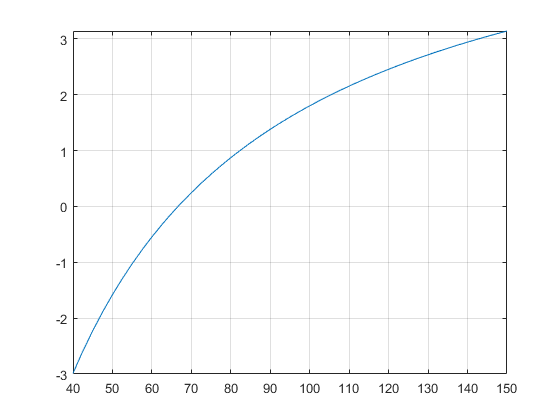

format long
g = 9.81;
cd = 0.25;
t = 4;
v = @(m) (sqrt(g*m/cd).*tanh(sqrt(g*cd./m)*t)) - 33;
x = [40,150];
fplot(v,x)
grid on;

masa = interpolacionLineal(v,60,70)

masa =   66.599993163105978
